# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

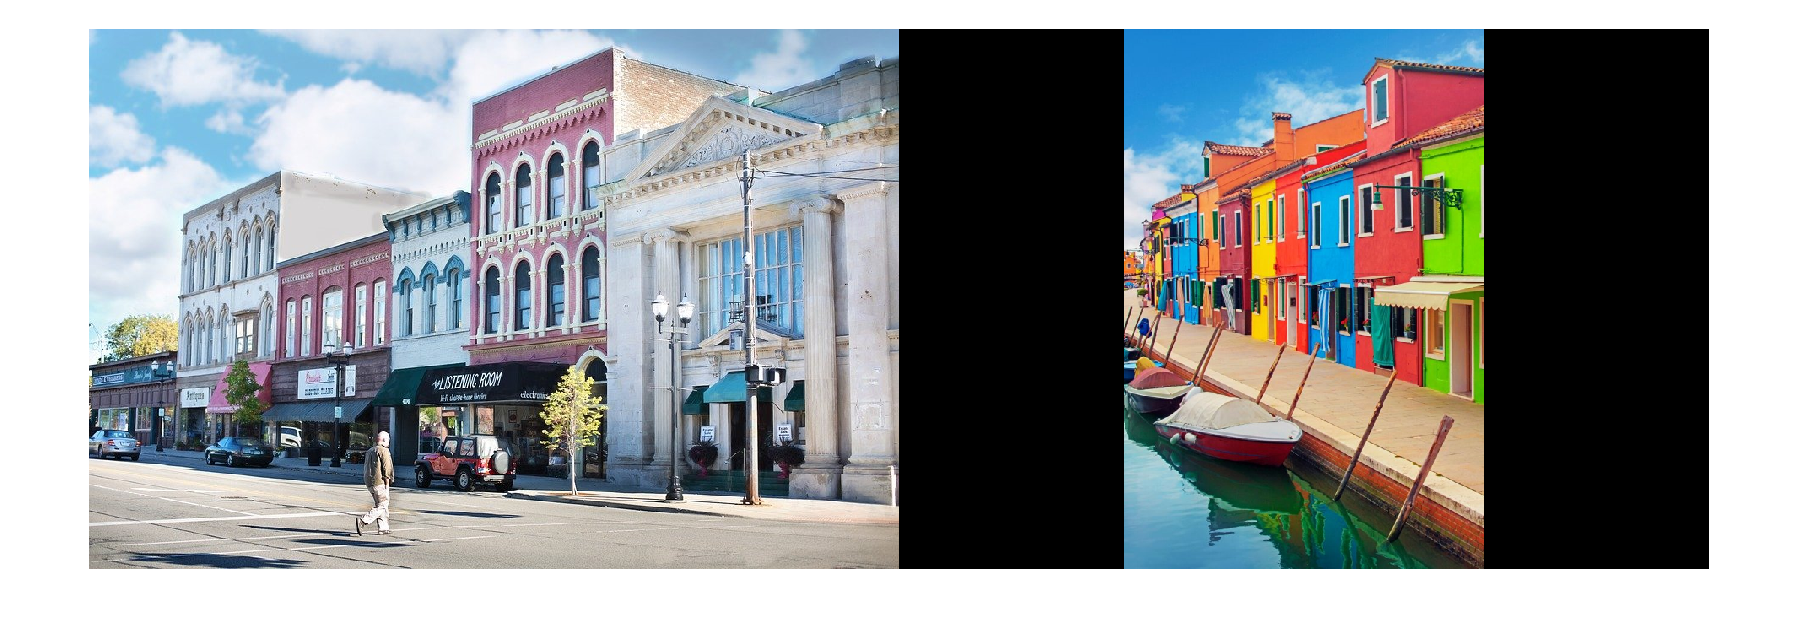

main_img = im2double(imread("colorful_town1.png"));
color_img = im2double(imread("city_block1.png"));
montage({color_img, main_img});

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.  

[x1, y1, c1] = size(main_img);
reshaped_main_img = reshape(main_img, x1*y1, c1);
[x2, y2, c2] = size(color_img);
reshaped_color_img = reshape(color_img, x2*y2, c1);

rgb_transform_to_lms = [0.3811 0.5783 0.0402; 0.1967 0.7244 0.0782; 0.0241 0.1288 0.844];
log_lms_transform_lab = ([1/3. 0. 0.; 0. 1/6. 0.; 0. 0. 1/2.].^(1/2)) * [1. 1. 1.; 1. 1. -2; 1. -1. 0.];

main_img_lms = rgb_transform_to_lms * reshaped_main_img.';
main_img_lms(main_img_lms == 0) = 1./255; % in case value in lms is too lowwww
main_img_lms_log = log(main_img_lms);
main_img_lab = log_lms_transform_lab * main_img_lms_log;

color_img_lms = rgb_transform_to_lms * reshaped_color_img.';
color_img_lms (color_img_lms == 0) = 1./255;
color_img_lms_log = log(color_img_lms);
color_img_lab = log_lms_transform_lab * color_img_lms_log;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

main_img_lab_mean = mean(main_img_lab, 2);
main_img_lab_std = std(main_img_lab, 1, 2);

color_img_lab_mean = mean(color_img_lab, 2);
color_img_lab_std = std(color_img_lab, 1, 2);

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

main_img_lab_sub_mean = main_img_lab - main_img_lab_mean;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

main_img_lab_adj = (color_img_lab_std ./ main_img_lab_std) .* main_img_lab_sub_mean;

Step 6: Add in the means of the lαβ channels for the source.

main_img_lms_adj_smean = main_img_lab_adj + color_img_lab_mean;

Step 7: Convert lαβ back to RGB color space.

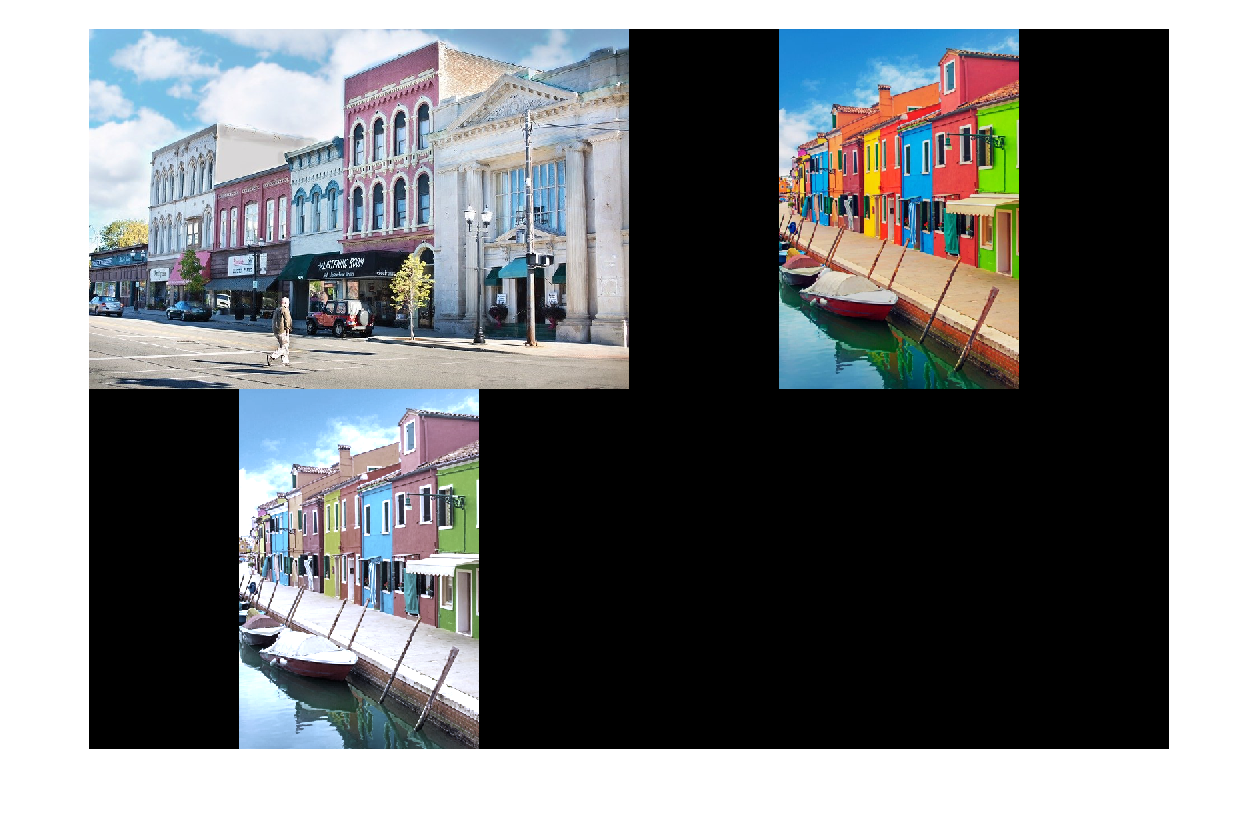

lab_transform_to_LMS = [1 1 1; 1 1 -1; 1 -2 0] * ([1/3. 0. 0.; 0. 1/6. 0.; 0. 0. 1/2.] .^ (1/2));
lms_transform_to_rgb = [4.4679 -3.5873 0.1193; -1.2186 2.3809, -0.1624; 0.0497 -0.2439 1.2045];

main_img_lms_adj = exp(lab_transform_to_LMS * main_img_lms_adj_smean);
main_img_rgb_adj = lms_transform_to_rgb * main_img_lms_adj;

main_img_rgb_adj = reshape(main_img_rgb_adj.', x1, y1, c1);

montage({color_img, main_img, main_img_rgb_adj});